# Estimation of neutrons diffraction peak splitting at JT transition in pure and Y-substituted TmVO4

## Pure TmVO4

#### Pseudospin equation

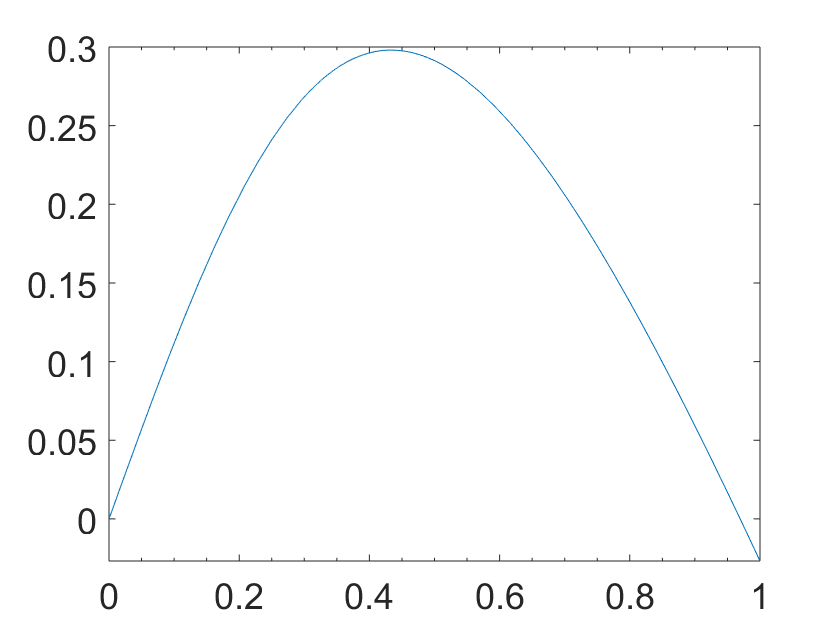

Tc = 2.15;% transition temperature of TmVO4
f = @(t,x) tanh(x/(t/Tc))-x;% pseudospin equation
fplot(@(x) f(1,x),[1e-3 1]);% plot equation

#### Extract pseudospin from equation

e = @(t) 3e-3*fzero(@(x) f(t,x),[1e-7 1]);
% expression of strain as a function of temperature

disp(["Splitting at Tc:",num2str(e(Tc-1e-7))])% test value

    "Splitting at Tc:"    "1.1206e-06"



disp(["Splitting at 0K:",num2str(e(1e-7))])% test value

    "Splitting at 0K:"    "0.003"



#### Distortion vs temperature at zero field

figure
fplot(e,Tc*[0 1-1e-7]);% cannot use range [0 1] due to boundary conditions

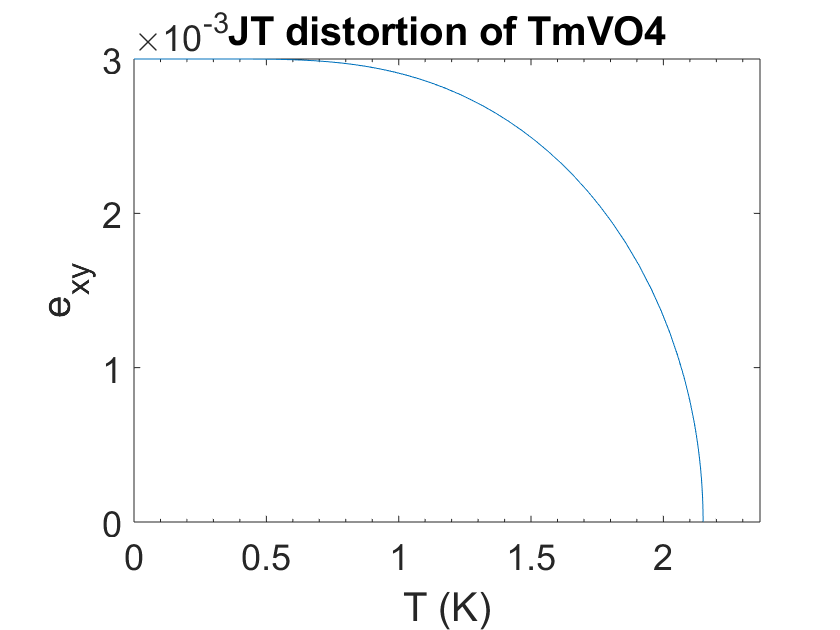

title("JT distortion of TmVO4");% after Segmüller et al. 1974
xlabel("T (K)");ylabel("e_{xy}");
xlim(Tc*[0 1.1]);

#### Modeling of neutrons peak at [8 8 0] as sum of Lorentzians

L1 = @(q,s,w) 1./((q+s).^2+w^2)+1./((q-s).^2+w^2);
% q: peak center; taken in reciprocal space
% s: half-splitting of the peak at the transition
% w: HWHM of the Lorentzian

#### Modeling parameters

w = 2.5e-3;% relative width of [880] peak measured at 5K
h = 8;% peak index h in [h80]
W = w*h;% effective width = relative width x peak index
q0 = h;% position of peak at high temp along [h80] direction
q = -2e-2:1e-4:2e-2;% relative plotting range
Q = q*h;% effective plotting range

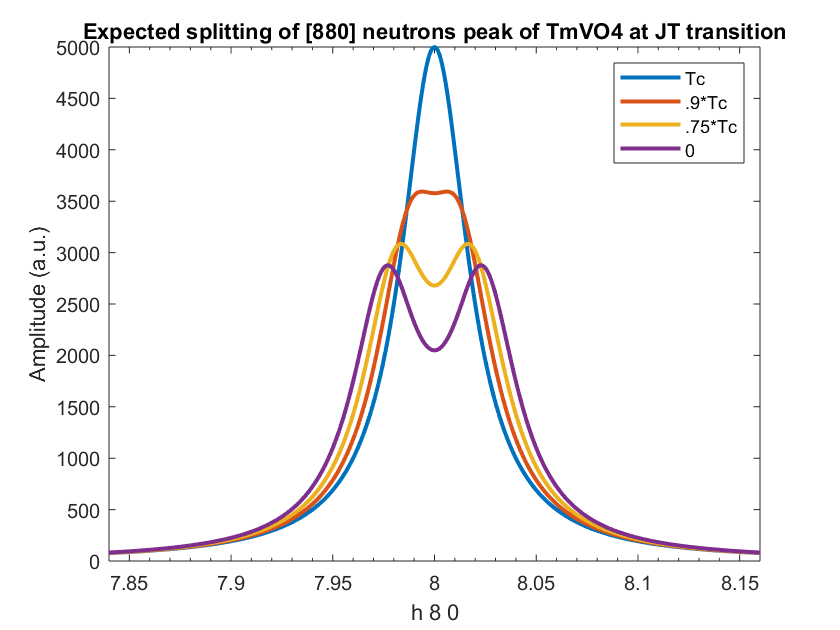

T1 = Tc-1e-7;% simulat peak at Tc
T2 = .75*Tc;
T3 = .9*Tc;
figure
plot(Q+q0,L1(Q,h*e(T1),W),'Displayname',"Tc")
hold on
plot(Q+q0,L1(Q,h*e(T3),W),'Displayname',".9*Tc")
plot(Q+q0,L1(Q,h*e(T2),W),'Displayname',".75*Tc")
plot(Q+q0,L1(Q,h*e(0),W),'Displayname',"0")
legend()
title("Expected splitting of [880] neutrons peak of TmVO4 at JT transition");
xlabel("h 8 0");ylabel("Amplitude (a.u.)");
xlim(q0+[min(Q) max(Q)]);

## 10% Y-substituted TmVO4

Ts = 1.5;% transition temperature of 10%Y-TmVO4
fs = @(t,x) tanh(x/(t/Ts))-x;% pseudospin equation
es = @(t) 2e-3*fzero(@(x) fs(t,x),[1e-7 1]);
% expression of strain as a function of temperature

#### Distortion vs temperature at zero field

figure
fplot(es,Ts*[0 1-1e-7]);% cannot use range [0 1] due to boundary conditions

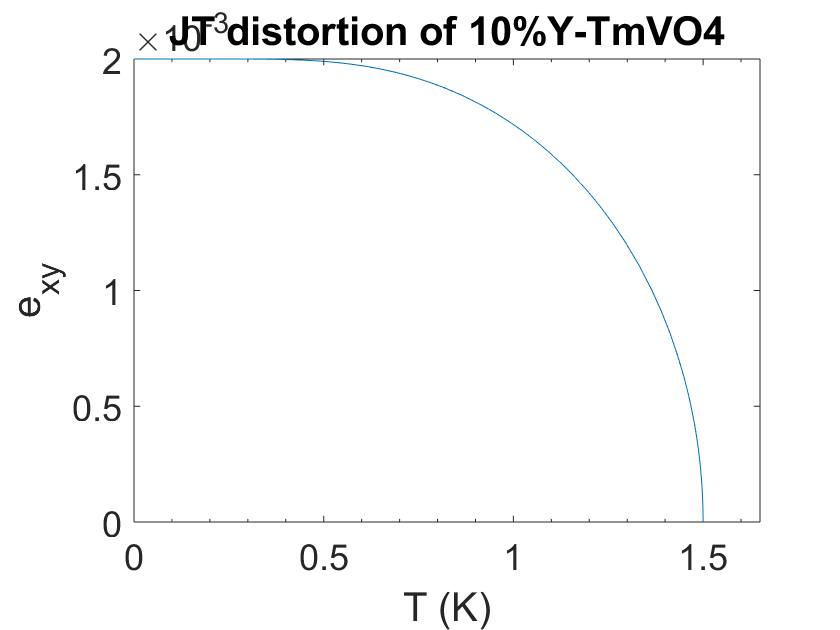

title("JT distortion of 10%Y-TmVO4");% after Segmüller et al. 1974
xlabel("T (K)");ylabel("e_{xy}");
xlim(Ts*[0 1.1]);

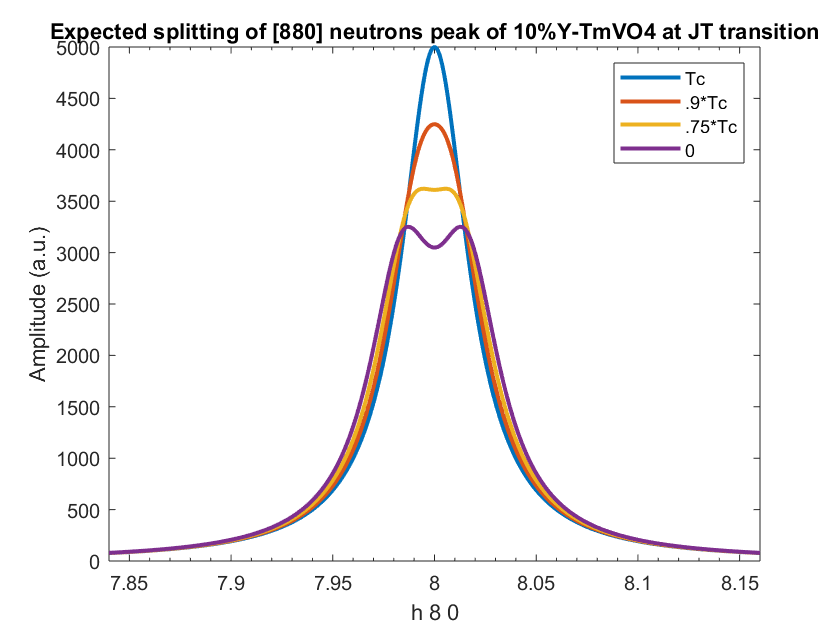

Ts1 = Ts-1e-7;% simulat peak at Tc
Ts2 = .75*Ts;
Ts3 = .9*Ts;
figure
plot(Q+q0,L1(Q,h*es(Ts1),W),'Displayname',"Tc")
hold on
plot(Q+q0,L1(Q,h*es(Ts3),W),'Displayname',".9*Tc")
plot(Q+q0,L1(Q,h*es(Ts2),W),'Displayname',".75*Tc")
plot(Q+q0,L1(Q,h*es(0),W),'Displayname',"0")
legend()
title("Expected splitting of [880] neutrons peak of 10%Y-TmVO4 at JT transition");
xlabel("h 8 0");ylabel("Amplitude (a.u.)");
xlim(q0+[min(Q) max(Q)]);